close all;
clearvars -except unnamed;  

activity = 1.9; %1.6 for LiClO4, 1.9 for LiPF6 in EMC/EC (0.02,0.11,7.6 for clyte diff) 1 for EMC solvent              
concs = linspace(0.05,0.95,19);
rxn_types = {'uniformly_valid_i0_fix'};
legend_names = {'unif i0 Fixed'};
conc_vec = [];
filenames = {};
l = 1;
%Set limits for how much of data to be used?
klow = 1;
khigh = 19;
temp_vec = [];


% 
% %6 Degree C
% T = 6;
% foldername_base = './NMC811_6C_3594/';
% filename_base = {'./NMC811_6C_3594/Li_'};
% Num_temps = (khigh-klow)+1;
% temp_vec = (273.15+T)*ones(1,Num_temps);
% for k=klow:khigh
%     conc_vec = [conc_vec, (1-concs(k))];
%     filenames{l} = append(filename_base{1},num2str(k),'.csv');
%     l=l+1;
% end
% 
% T = 6;
% filename_base = {'./NMC811_6C/Li_'};    
% Num_temps = (khigh-klow)+1;
% temp_vec = [temp_vec,(273.15+T)*ones(1,Num_temps)];
% for k=klow:khigh
%     conc_vec = [conc_vec, (1-concs(k))];
%     filenames{l} = append(filename_base{1},num2str(k),'.csv');
%     l=l+1;
% end


%%15 Degree C
T = 15;
filename_base = {'./NMC811_15C/Li_'};    
Num_temps = (khigh-klow)+1;
temp_vec = [temp_vec,(273.15+T)*ones(1,Num_temps)];
for k=klow:khigh
    conc_vec = [conc_vec, (1-concs(k))];
    filenames{l} = append(filename_base{1},num2str(k),'.csv');
    l=l+1;
end

T = 15;
foldername_base = './NMC811_15C_1915/';
filename_base = {'./NMC811_15C_1915/Li_'};    
Num_temps = (khigh-klow)+1;
temp_vec = [temp_vec,(273.15+T)*ones(1,Num_temps)];
for k=klow:khigh
    conc_vec = [conc_vec, 0.7*(1-concs(k))+0.3];
    filenames{l} = append(filename_base{1},num2str(k),'.csv');
    l=l+1;
end


% %25 Degree C
% T = 25;
% foldername_base = './NMC811_25C/';
% filename_base = {'./NMC811_25C/Li_'};
% Num_temps = (khigh-klow)+1;
% temp_vec = [temp_vec,(273.15+T)*ones(1,Num_temps)];
% for k=klow:khigh
%     conc_vec = [conc_vec, 1-concs(k)];
%     filenames{l} = append(filename_base{1},num2str(k),'.csv');
%     l=l+1;
% end
% 
% T = 25;
% foldername_base = './NMC811_25C_3601/';
% filename_base = {'./NMC811_25C_3601/Li_'};
% Num_temps = (khigh-klow)+1;
% temp_vec = [temp_vec,(273.15+T)*ones(1,Num_temps)];
% for k=klow:khigh
%     conc_vec = [conc_vec, 1-concs(k)];
%     filenames{l} = append(filename_base{1},num2str(k),'.csv');
%     l=l+1;
% end

./NMC811_15C/Li_1.csv
./NMC811_15C/Li_2.csv
./NMC811_15C/Li_3.csv
./NMC811_15C/Li_4.csv
./NMC811_15C/Li_5.csv
./NMC811_15C/Li_6.csv
./NMC811_15C/Li_7.csv
./NMC811_15C/Li_8.csv
./NMC811_15C/Li_9.csv
./NMC811_15C/Li_10.csv
./NMC811_15C/Li_11.csv
./NMC811_15C/Li_12.csv
./NMC811_15C/Li_13.csv
./NMC811_15C/Li_14.csv
./NMC811_15C/Li_15.csv
./NMC811_15C/Li_16.csv
./NMC811_15C/Li_17.csv
./NMC811_15C/Li_18.csv
./NMC811_15C/Li_19.csv
./NMC811_15C_1915/Li_1.csv
./NMC811_15C_1915/Li_2.csv
./NMC811_15C_1915/Li_3.csv
./NMC811_15C_1915/Li_4.csv
./NMC811_15C_1915/Li_5.csv
./NMC811_15C_1915/Li_6.csv
./NMC811_15C_1915/Li_7.csv
./NMC811_15C_1915/Li_8.csv
./NMC811_15C_1915/Li_9.csv
./NMC811_15C_1915/Li_10.csv
./NMC811_15C_1915/Li_11.csv
./NMC811_15C_1915/Li_12.csv
./NMC811_15C_1915/Li_13.csv
./NMC811_15C_1915/Li_14.csv
./NMC811_15C_1915/Li_15.csv
./NMC811_15C_1915/Li_16.csv
./NMC811_15C_1915/Li_17.csv
./NMC811_15C_1915/Li_18.csv
./NMC811_15C_1915/Li_19.csv
Slope Values : \n
    0.0791
    0.1875
    0.431


 unif i0 Fixed BIC:-3872.48935 



 unif i0 Fixed Chi-squared:5.63568 


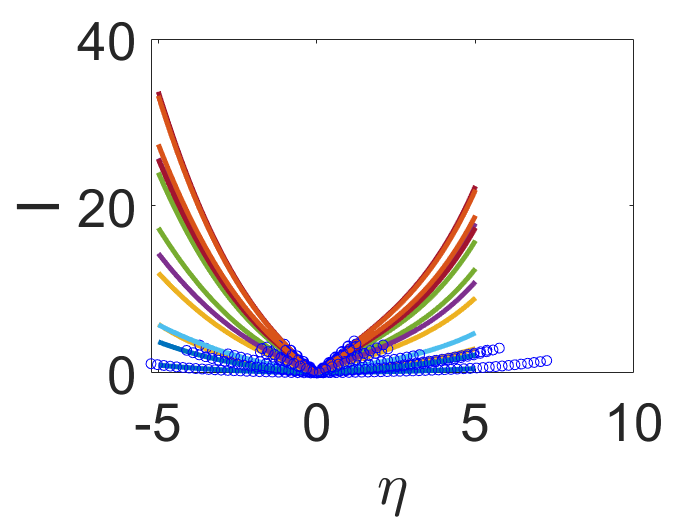

Num_temps = size(temp_vec,2);
for j=1:size(rxn_types,2)
[f_fit,tht_fit,cost_val,chi_squared,BIC,size_vec,xdata,ydata,xvalues] = get_fit_2(temp_vec,conc_vec,filenames,rxn_types{j},activity);
fprintf('\n %s BIC:%0.5f \n',legend_names{j},BIC);
fprintf('\n %s Chi-squared:%0.5f \n',legend_names{j},chi_squared);
size_vec_2 = 200*ones(size(filenames,2),1);
figure(1);
set(findall(gcf,'-property','FontSize'),'FontSize',32);
[X_vals,idx] = sort(xvalues(1:size_vec_2(1)));
[X_vals2,idx2] = sort(xdata(1:size_vec(1)));
Y_vals = f_fit(1:size_vec_2(1));
plot(X_vals,abs(Y_vals(idx)),'LineWidth',3);

hold on;
hold on;
if j == size(rxn_types,2)
    Ydata = ydata(1:size_vec(1));
    plot(X_vals2,abs(Ydata(idx2)),'bo');
    xlabel('${\eta}$','Interpreter',"latex");
    ylabel('I');
%     legend(legend_names,"Location","southeast");
end

for i=2:Num_temps
if mod(i,3) == 0
set(findall(gcf,'-property','FontSize'),'FontSize',32);
S = sum(size_vec(1:i-1),'all');
S2 = sum(size_vec_2(1:i-1),'all');
[X_vals,idx] = sort(xvalues(S2+1:S2+size_vec_2(i)));
[X_vals2,idx2] = sort(xdata(S+1:S+size_vec(i)));
Y_vals = f_fit(S2+1:S2+size_vec_2(i));
plot(X_vals,abs(Y_vals(idx)),'LineWidth',3);
hold on;
if j == size(rxn_types,2)
    Ydata = ydata(S+1:S+size_vec(i));
    plot(X_vals2,abs(Ydata(idx2)),'bo');
    xlabel('${\eta}$','Interpreter',"latex");
    ylabel('I');
%     legend(legend_names,"Location","southeast");
end
end
end
end

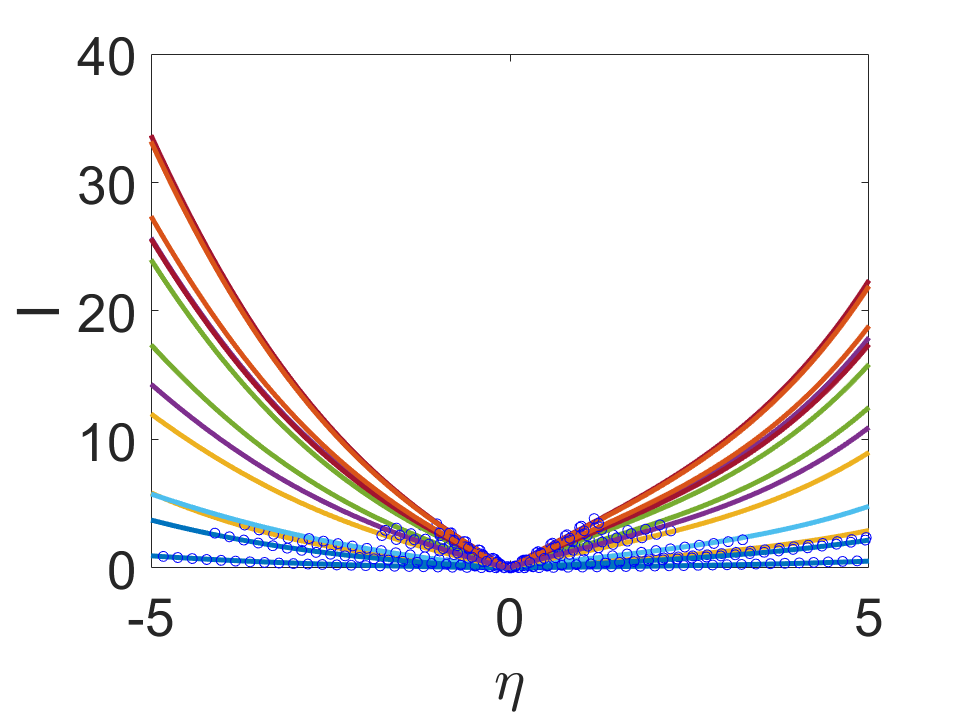

% Get the current figure handle
fig = gcf;
xlim([-5 5]);

% Set up the export settings
fig.Units = 'inches';
fig.Position = [0 0 8 6];  % [left bottom width height]

% Set resolution (higher number for better quality)
resolution = 300;  % dots per inch

% % Specify the full path and filename (SET YOUR CHOSEN PATH)
% filename = ['C:\Users\ChemeGrad2021\MIT Dropbox\Shakul Pathak\Konrad\Fitting Codebase\' foldername_base '\fit_unif.jpg'];

% Export the figure
exportgraphics(fig, filename, 'Resolution', resolution);

disp(['lambda =' num2str(tht_fit(1))])

\lambda =12.7893


disp(['beta_red =' num2str(tht_fit(2))])

\beta_red =3.7444


disp(['beta_ox =' num2str(tht_fit(3))])

\beta_ox =2.3304
